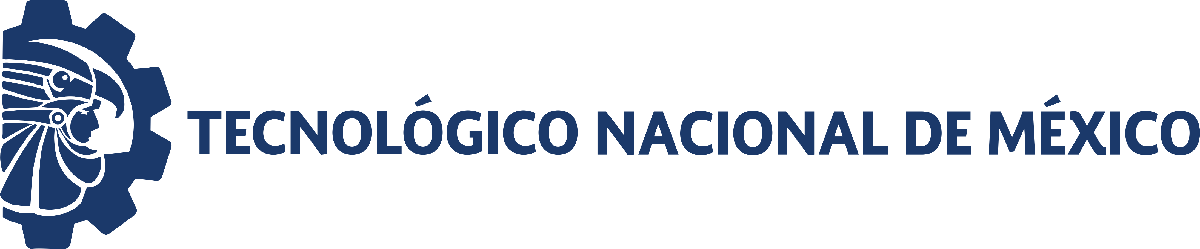                                 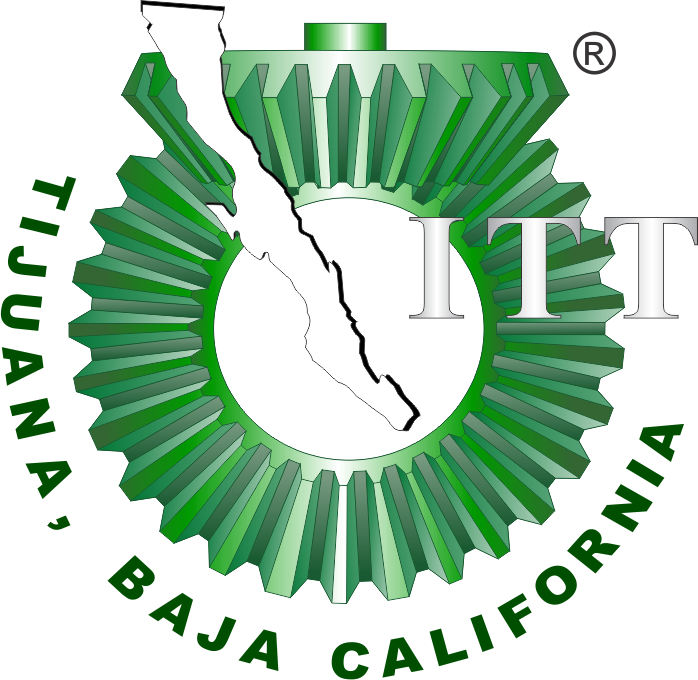

# Práctica 1: Leyes de crecimiento exponencial 

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Nombres y Apellidos**

Número de control: **12345678**

Correo institucional: **xxx.xxx@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation data

clc; clear; close all; warning('off','all')

## Exponential growth


$$\dot{x} =\textrm{kx}$$


dt = 0.5; %Integration step
x0 = 1; %Initial condition
k = 0.5; %Growth rate (parameter)
tend = 10; %Simulation final time

[t,x1,x2,x3] = sys_expgrowth(dt,x0,k,tend);
plotl1(t,x1,x2,x3)

function [t,x1,x2,x3] = sys_expgrowth(dt,x0,k,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x2 = zeros(numel(t),1); x2(1) = x0;
    x3 = zeros(numel(t),1); x3(1) = x0;

    %% Analytical solution
    x1 = x0*exp(k*t);

    %% Euler's method
    for i = 1:n
        x2(i+1) = x2(i) + (k*x2(i))*dt;
    end

    %% Heun's method
    for i = 1:n
        [fx3] = f(x3(i));
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n);
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2;
    end

    function [dx3] = f(x3)
        dx3 = k*x3;
    end
end

function plotl1(t,x1,x2,x3)
    set(figure(1),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    mycolors = [0.12,0.41,0.55; 0.25,0.51,0.47; 0.91,0.66,0.07;...
                0.00,0.25,0.40; 0.50,0.10,0.05; 0.85,0.35,0.05;...
                0.25,0.25,0.25; 0.30,0.50,0.20];
    shuffledcolors = mycolors(randperm(size(mycolors,1)),:);

    hold on; box on; grid off; colororder(shuffledcolors)

    plot(t,x1,'-','LineWidth',1)
    plot(t,x2,'--','LineWidth',1)
    plot(t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$','Interpreter','latex')
    ylabel('$x_i(t)$ $[units]$','Interpreter','latex')
    L = legend('$x_1(t):Analytical$','$x_2(t):Euler$','$x_3(t):Heun$');
    set(L,'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Exponential growth')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 150]); yticks(0:25:150)

    exportgraphics(gcf,'exponential growth.pdf','ContentType','vector')
end

## Exponential decay


$$\dot{x} =-\textrm{kx}$$


Look for the point in the plot where $x\left(t\right)=\frac{x_0 }{2}$ (half-life, $t_{1/2}$) and compute the decay rate of the bioprocess, where $k=\frac{\textrm{ln2}}{t_{1/2} }$.

dt = 0.1; %Integration step
x0 = 1; %Initial condition
k = 0.5; %Growth rate (parameter)
tend = 10; %Simulation final time

[t,x1,x2,x3] = sys_expdecay(dt,x0,k,tend);
plotl2(t,x1,x2,x3)

function [t,x1,x2,x3] = sys_expdecay(dt,x0,k,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x2 = zeros(numel(t),1); x2(1) = x0;
    x3 = zeros(numel(t),1); x3(1) = x0;

    %% Analytical solution
    x1 = x0*exp(-k*t);

    %% Euler's method
    for i = 1:n
        x2(i+1) = x2(i) + (-k*x2(i))*dt;
    end

    %% Heun's method
    for i = 1:n
        [fx3] = f(x3(i));
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n);
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2;
    end

    function [dx3] = f(x3)
        dx3 = -k*x3;
    end
end

function plotl2(t,x1,x2,x3)
    set(figure(2),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    mycolors = [0.12,0.41,0.55; 0.25,0.51,0.47; 0.91,0.66,0.07;...
                0.00,0.25,0.40; 0.50,0.10,0.05; 0.85,0.35,0.05;...
                0.25,0.25,0.25; 0.30,0.50,0.20];
    shuffledcolors = mycolors(randperm(size(mycolors,1)),:);

    hold on; box on; grid off; colororder(shuffledcolors)

    plot(t,x1,'-','LineWidth',1)
    plot(t,x2,'--','LineWidth',1)
    plot(t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$','Interpreter','latex')
    ylabel('$x_i(t)$ $[units]$','Interpreter','latex')
    L = legend('$x_1(t):Analytical$','$x_2(t):Euler$','$x_3(t):Heun$');
    set(L,'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Exponential decay')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 1.1]); yticks(0:0.1:1.1)

    exportgraphics(gcf,'exponential decay.pdf','ContentType','vector')
end

## First-order pharmacokinetics [modified exponential decay]: Controlled drug delivery by nanohydrogels


$$\dot{x} =\beta \left(1-e^{-\textrm{kt}} \right)$$


**Reference: **González‐Ayón, M. A., Sañudo‐Barajas, J. A., Picos‐Corrales, L. A., & Licea‐Claverie, A. (2015). PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil. *Journal of Polymer Science Part A: Polymer Chemistry*, *53*(22), 2662-2672. doi: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

### Experimental data

clc; clear; close all
sys = readmatrix('data.csv');
t = round(sys(:,1));
x1 = sys(:,2); x2 = sys(:,3); x3 = sys(:,4); x4 = sys(:,5);
T = array2table([t,x1,x2,x3,x4],'VariableNames',{'t [min]','N32','N35','N36','N45'}); disp(T)

### Nonlinear regression and biostatistics

rho = [0.1, 100];
mdl_x1 = pharmacokinetics(t,x1,rho); y1 = mdl_x1.Fitted; % Nanohydrogel N32
mdl_x2 = pharmacokinetics(t,x2,rho); y2 = mdl_x2.Fitted; % Nanohydrogel N35
mdl_x3 = pharmacokinetics(t,x3,rho); y3 = mdl_x3.Fitted; % Nanohydrogel N36
mdl_x4 = pharmacokinetics(t,x4,rho); y4 = mdl_x4.Fitted; % Nanohydrogel N45
plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)

### Functions

function mdl = pharmacokinetics(to,xo,rho)

    function xi = model(rho,t)
        k = rho(1); beta = rho(2);
        xi = beta*(1 - exp(-k*t));
    end

    mdl = fitnlm(to,xo,@model,rho);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1 - alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['k   ';'beta'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(rho))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Studen value: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])

    disp(Results)
end

function plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)
    set(figure(3),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'Fontname','Times New Roman')
    fontsize(10,'points')
    mycolors = [0.00,0.25,0.40;0.25,0.51,0.47;...
                0.91,0.66,0.07;0.85,0.35,0.05];
    %shuffledcolors = mycolors(randperm(size(mycolors,1)),:);
    hold on; box on; grid off; colororder(mycolors)
    % Experimental data
    plot(t,x1,'x','MarkerSize',5,'LineWidth',1)
    plot(t,x2,'o','MarkerSize',5,'LineWidth',1)
    plot(t,x3,'square','MarkerSize',5,'LineWidth',1)
    plot(t,x4,'diamond','MarkerSize',5,'LineWidth',1)
    % Fitted values
    plot(t,y1,'-','LineWidth',1)
    plot(t,y2,'-','LineWidth',1)
    plot(t,y3,'-','LineWidth',1)
    plot(t,y4,'-','LineWidth',1)

    xlabel('$t$ $[min]$','Interpreter','latex')
    ylabel('Cumulative drug release $[\%]$','Interpreter','latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 100]); yticks(0:10:100)

    L = legend('$x_1(t):N32$','$x_2(t):N35-VP15$',...
        '$x_3(t):N36-2MBA3$','$x_4(t):N45-2MBA12$');
    set(L,'Interpreter','latex','Location','SouthEast','Box','Off')

    exportgraphics(gcf,'nanohydrogels.pdf','ContentType','Vector')
    exportgraphics(gcf,'nanohydrogels.png','Resolution',600)
    exportgraphics(gcf,'nanohydrogels.jpg','Resolution',600)
    print('nanohydrogels','-dsvg')
    print('nanohydrogels','-depsc')
end

## Chemotherapy dynamics in the blood compartment

Assume that the chemotherapy drug within the blood compartment follows a first-order kinetics. Let us apply the modified exponential decay to illustrate the dynamics of this drug when administered with the following scheme:

- **Protocol:** (3 Imatinib intakes every 2 days + 7 days of rest)* 2 cycles.

- **Dosing:** 300 mg/day per dose.

- **Application frequency:** One dose every 2 days.

- **Doses per cycle:** 3 doses.

- **Number of cycles:** 2 cycles.

- **Imatinib biological half-life **$\left\lbrack t_{1/2} \right\rbrack$**:** 18 hours [0.75 days]. [https://go.drugbank.com/drugs/DB00619](https://go.drugbank.com/drugs/DB00619)

- **ODE:** $\dot{x} =\phi \left(t\right)-\mu x$

clc; clear; close all; warning('off','all')

### Time: Hours

dt = 0.01; dose = 300; mu = log(2)/18; tend = 21*24;

phi = zeros(tend/dt+1,1);
% Cycle 1
phi(1:1/dt) = dose;
phi(2*24/dt:(2*24+1)/dt) = dose;
phi(4*24/dt:(4*24+1)/dt) = dose;
%Cycle 2
phi(11*24/dt:(11*24+1)/dt) = dose;
phi(13*24/dt:(13*24+1)/dt) = dose;
phi(15*24/dt:(15*24+1)/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend);
plotchemo(t/24,phi,x,'hours')

### Time: days

dt = 0.01; dose = 300; mu = log(2)/(18/24); tend = 24;

phi = zeros(tend/dt+1,1);
% Cycle 1
phi(1:1/dt) = dose;
phi(2/dt:3/dt) = dose;
phi(4/dt:5/dt) = dose;
% Cycle 2
phi(11/dt:12/dt) = dose;
phi(13/dt:14/dt) = dose;
phi(15/dt:16/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend);
plotchemo(t,phi,x,'days')

### Functions

function [t,x] = sys_chemo(dt,mu,phi,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(numel(t),1);
    
    % Heun's method
    for i=1:n
        [fx] = f(x(i),phi(i));
        xn = x(i) + fx*dt;
        [fxn] = f(xn,phi(i));

        x(i+1) = x(i) + (fx + fxn)*dt/2;
    end
    function [dx] = f(x,phi)
        dx = phi - mu*x;
    end
end

function plotchemo(t,phi,x,time)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,20])
    
    subplot(2,1,1)
    set(gca,'Fontname','Times New Roman')
    fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,phi,'-','LineWidth',1,'Color',[0.25,0.25,0.25])
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$\phi(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 350]); yticks(0:50:350)

    subplot(2,1,2)
    set(gca,'Fontname','Times New Roman')
    fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',[0.50,0.10,0.05])
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 400]); yticks(0:50:400)
    
    exportgraphics(gcf,['chemo ',time,'.pdf'],'ContentType','Vector')
end